# Charge amplifier

Copyright (C) 2021 Miodrag Bolic

  This program is free software: you can redistribute it and/or modify   it under the terms of the GNU General Public License as published by  the Free Software Foundation, either version 3 of the License, or  (at your option) any later version.  This program is distributed in the hope that it will be useful, but WITHOUT ANY WARRANTY; without even the implied warranty of MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the GNU General Public License for more details <https://www.gnu.org/licenses/>. 

This code was developed by Miodrag Bolic for the book PERVASIVE CARDIAC AND RESPIRATORY MONITORING DEVICES: [https://github.com/Health-Devices/CARDIAC-RESPIRATORY-MONITORING](https://github.com/Health-Devices/CARDIAC-RESPIRATORY-MONITORING) 

## Introduction

This notebook provides introduction to the charge amplifier circuit connected to the model of the piezoelectric transducer. This circuit is based on Analog Devices application note: [12-Bit, 1 MSPS, Single-Supply, Two-Chip Data Acquisition System for Piezoelectric Sensors](https://www.analog.com/media/en/reference-design-documentation/reference-designs/CN0350.pdf). 

plotting=1;
start_time=1000;
end_time=1500;
open_system('ChargeAmpl1')
simOut = sim('ChargeAmpl1', 'CaptureErrors', 'on');

Plotting results:

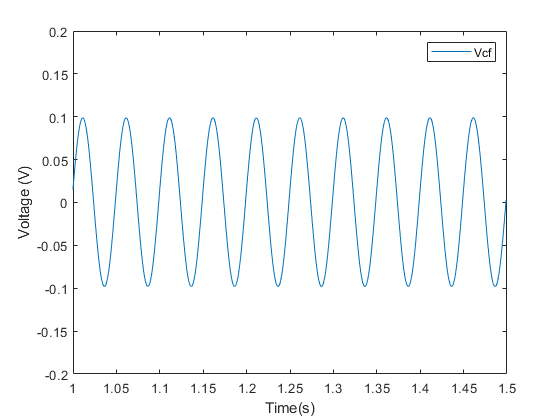

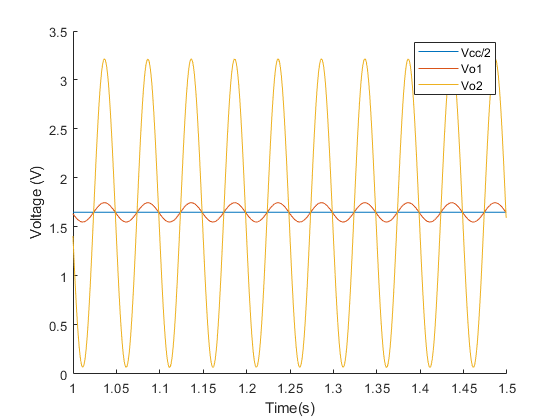

if plotting ==1
    figure
    plot(VCf.Time(start_time:end_time), VCf.Data(start_time:end_time))
    xlabel("Time(s)")
    ylabel("Voltage (V)")
    xlim([1,1.5]);
    ylim([-0.2,0.2])
    legend("Vcf");
    %figure
    %plot(i.Time(start_time:end_time), i.Data(start_time:end_time))
    figure
    hold on, plot(V.Time(start_time:end_time), 1.65*ones(1,end_time-start_time+1))
    plot(Vo1.Time(start_time:end_time), Vo1.Data(start_time:end_time))
    plot(Vo2.Time(start_time:end_time), Vo2.Data(start_time:end_time)) 
    xlabel("Time(s)")
    ylabel("Voltage (V)")
    legend("Vcc/2","Vo1","Vo2");
    xlim([1,1.5])
end

**Excersize**: Modify simulation in Simscape to include different inputs from the block called Signal Builder in the group "Generating dq/dt". Assume that the acceleration change as a pulse or that it keep increasing. Explain the results.